## **Calculate the rolling VaR of a series of portfolio returns.**

For the normal distribution method, assume that the profit and loss of the portfolio is normally distributed. Using this assumption, compute the VaR by multiplying the *z*-score, at each confidence level by the standard deviation of the returns. Because VaR backtesting looks retrospectively at data, the VaR "today" is computed based on values of the returns in the last *N* = 250 days (or an estimation window size specified by the user) leading to, but not including, "today."

Load Returns data

Data = load('PortfolioReturns.mat');
Returns = Data.Returns;
DateReturns = Data.DateReturns;
confidence = [95 99];
EstimationWindowSize = 250;

Define the estimation window as 250 trading days. The test window starts on the first day in 1996 and runs through the end of the sample.

SampleSize = length(Returns);
TestWindowStart      = find(year(DateReturns)==1996,1);
TestWindow           = TestWindowStart : SampleSize;


For a VaR confidence level of 95% and 99%, set the complement of the VaR level.

pVaR = 1 - confidence/100;

These values mean that there is at most a 5% and 1% probability, respectively, that the loss incurred will be greater than the maximum threshold (that is, greater than the VaR).

**Compute the VaR Using the Normal Distribution Method**

For the normal distribution method, assume that the profit and loss of the portfolio is normally distributed. Using this assumption, compute the VaR by multiplying the *z*-score, at each confidence level by the standard deviation of the returns. Because VaR backtesting looks retrospectively at data, the VaR "today" is computed based on values of the returns in the last *N* = 250 days leading to, but not including, "today."

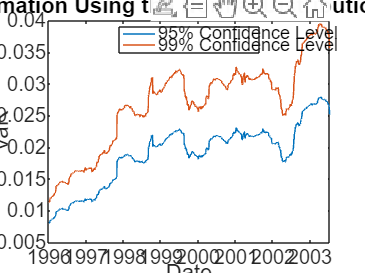

Zscore   = norminv(pVaR);
Sigma = zeros(length(TestWindow),1);

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t-EstimationWindowSize:t-1;
    Sigma(i) = std(Returns(EstimationWindow)); 
end

NormVar = -Sigma*Zscore;

figure;
plot(DateReturns(TestWindow),NormVar)
xlabel('Date')
ylabel('VaR')
legend(confidence + "% Confidence Level","Location","Best")
title('VaR Estimation Using the Normal Distribution Method')